# Example: COVID-2019 data for Italy (22-Jan-2020-18-Mar-2020)

I am taking some data, collected into DATA.mat from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Confirmed patient" used in the database does not precise whether they have been quarantined or not. In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('DATA.mat','tableRecovered','tableDeaths','tableConfirmed','time')

try
    indLocation = find(contains(tableRecovered.CountryRegion,'Italy')==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,'Italy')
    indLocation = find([searchLoc{:}]==1)
end

tableRecovered(indLocation,1:2)

ans = 1×2 table
    ProvinceState    CountryRegion
    _____________    _____________

     {0×0 char}        {'Italy'}  


indLocation = indLocation(1)

indLocation = 18


Recovered = table2array(tableRecovered(indLocation,5:end));
Deaths = table2array(tableDeaths(indLocation,5:end));
Confirmed = table2array(tableConfirmed(indLocation,5:end));

% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases

minNum= 40;
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

Npop= 60e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.06,1.2,1/5,1/40,0.01,0.02,0.01,0.02]; % my guess for the fit
E0 = Confirmed(1); % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Confirmed(1); % Initial number of infectious cases (we do not know it, so it is the number of quarantined)
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     2.81367e+09                      1.89e+10
     1         18      8.9303e+08       0.188917       8.49e+09      
     2         27     3.70247e+08      0.0719847       1.06e+11      
     3         36     4.32817e+07      0.0662572       1.29e+09      
     4         45     4.32817e+07       0.140232       1.29e+09      
     5         54     3.02401e+07       0.035058       5.45e+08      
     6         63     1.70286e+07       0.070116       6.43e+08      
     7         72     1.04629e+07      0.0457883       2.33e+08      
     8         81     9.36443e+06       0.029483       4.71e+07      
     9         90     9.17964e+06       0.130614       1.39e+09      
    10         99      8.7748e+06      0.0326534       8.35e+08      
    11        108     8.53095e+06      0.0653069       3.57e+09      
    12        117     8.00944e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,3,25,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

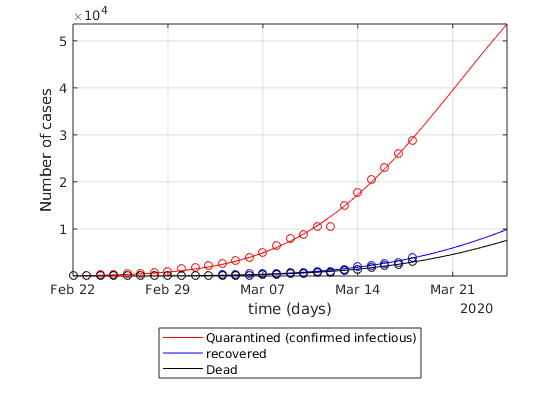

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
 set(gca,'yscale','lin')